%this project calculates the average speeds of the flies. The whole code
%can be run at once.
expmt.data.time

ans =   172788×1 RawDataField array with properties:

          raw: [172788×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/31.08/19.30-overnight, AJagar, geo in agar/08-31-2021-19-27-01__Basic_Tracking_1-1_Day1/raw_data/08-31-2021-19-27-01__time.bin'
          fID: 4
          dim: [172788 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1


reset(expmt.data.time)

ans =   172788×1 RawDataField array with properties:

          raw: [172788×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/31.08/19.30-overnight, AJagar, geo in agar/08-31-2021-19-27-01__Basic_Tracking_1-1_Day1/raw_data/08-31-2021-19-27-01__time.bin'
          fID: 4
          dim: [172788 1]
    precision: 'single'


interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw();

out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:}) %concatenate all the cells vertically

out = 863940×2 single matrix
       NaN       NaN
       NaN       NaN
       NaN       NaN
   68.2727   73.1250
   68.7444   73.1556
   68.9247   73.0538
   68.7582   73.0989
   68.8333   72.7778
   69.5960   72.8990
   69.7263   72.2105


writematrix(out,'testing.csv')
%asign quadrant to each point
out(out(:,1)>511.9776 & out(:,2)>511.9776,3) = 1;
out(out(:,1)<511.9776 & out(:,2)>511.9776,3) = 2;
out(out(:,1)<511.9776 & out(:,2)<511.9776,3) = 3;
out(out(:,1)>511.9776 & out(:,2)<511.9776,3) = 4;

%calculate the distance between successive coordinates of a trace. NAs are not removed, it only calculates the distance between two successive points
%with real values. As at the start of each experiment, there are few NAs,
%these can serve to separate the different traces after we use num2cell
%and vertcat, so a value will only be calculated for successive values of
%the same trace. Identity may not be preserved during colisions, but that
%is not important for this speed calculation
interval = mean(interframe_interval)

interval = single
0.1250

for i = 1:size(out,1)
    if i < size(out,1)
        out(i,4) = (sqrt((out(i,1)-out(i+1,1)).*(out(i,1)-out(i+1,1))+(out(i,2)-out(i+1,2)).*(out(i,2)-out(i+1,2))))/interval;
   
    else 
        out(i,4) = 0
    end
end

out = 863940×4 single matrix
       NaN       NaN         0       NaN
       NaN       NaN         0       NaN
       NaN       NaN         0       NaN
   68.2727   73.1250    3.0000    3.7814
   68.7444   73.1556    3.0000    1.6562
   68.9247   73.0538    3.0000    1.3799
   68.7582   73.0989    3.0000    2.6381
   68.8333   72.7778    3.0000    6.1771
   69.5960   72.8990    3.0000    5.6051
   69.7263   72.2105    3.0000   10.1789


%just getting the desired values in the matrix called final
speed = out(:,4);
pos = out(:,3)

pos = 863940×1 single column vector
     0
     0
     0
     3
     3
     3
     3
     3
     3
     3



final = horzcat(speed,pos)

final = 863940×2 single matrix
       NaN         0
       NaN         0
       NaN         0
    3.7814    3.0000
    1.6562    3.0000
    1.3799    3.0000
    2.6381    3.0000
    6.1771    3.0000
    5.6051    3.0000
   10.1789    3.0000



T = array2table(final)

T = 863940×2 table
    final1    final2
    ______    ______

       NaN      0   
       NaN      0   
       NaN      0   
    3.7814      3   
    1.6562      3   
    1.3799      3   
    2.6381      3   
    6.1771      3   
    5.6051      3   
    10.179      3   
     6.589      3   
    2.2885      3   
     1.513      3   
    1.3659      3   
    5.2417      3   
    4.5057      3   


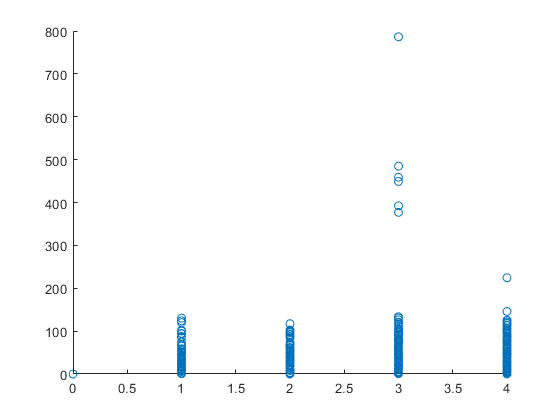


scatter(T.final2, T.final1)

%starting with a value of 0 for each quadrant (C1-4), and a count of 0 for
%each quadrant (count1-4), everytime a trace is followed by a successive
%trace (no NAs in between), we add the speed at point to the corresponding
%C, and add 1 to the corresponding count
C1=0

C1 = 0

count1=0

count1 = 0

C2=0

C2 = 0

count2=0

count2 = 0

C3=0

C3 = 0

count3=0

count3 = 0

C4=0

C4 = 0

count4=0

count4 = 0

count0=0

count0 = 0


  for i = 1:(size(final,1)-1)
    if final(i,2) == 1 && final(i+1,2) ~=0  
 C1= C1 + final(i,1)
 count1=count1+1
    elseif  final(i,2) == 2 && final(i+1,2) ~=0  
C2 = C2 + final(i,1)
count2=count2+1
    elseif final(i,2) == 3 && final(i+1,2) ~=0  
C3 = C3 + final(i,1)
count3=count3+1
    elseif final(i,2) == 4 && final(i+1,2) ~=0  
C4 = C4 +final(i,1)
count4=count4+1
    elseif final(i,2) == 0
count0=count0+1
    else 
    end
  end

count0 = 1

count0 = 2

count0 = 3

C3 = single
3.7814

count3 = 1

C3 = single
5.4375

count3 = 2

C3 = single
6.8174

count3 = 3

C3 = single
9.4555

count3 = 4

C3 = single
15.6326

count3 = 5

C3 = single
21.2377

count3 = 6

C3 = single
31.4166

count3 = 7

C3 = single
38.0056

count3 = 8

C3 = single
40.2941

count3 = 9

C3 = single
41.8071

count3 = 10

C3 = single
43.1730

count3 = 11

C3 = single
48.4147

count3 = 12

C3 = single
52.9204

count3 = 13

C3 = single
54.1945

count3 = 14

C3 = single
59.7988

count3 = 15

C3 = single
65.2445

count3 = 16

C3 = single
71.4085

count3 = 17

C3 = single
74.6761

count3 = 18

C3 = single
77.9784

count3 = 19

C3 = single
80.6143

count3 = 20

C3 = single
87.1901

count3 = 21

C3 = single
95.6629

count3 = 22

C3 = single
102.7593

count3 = 23

C3 = single
111.4911

count3 = 24

C3 = single
118.2088

count3 = 25

C3 = single
122.9222

count3 = 26

C3 = single
127.0649

count3 = 27

C3 = single
134.1130

count3 = 28

C3 = single
136.5762

count3 = 29

C3 = single
149.7944

count3 = 30

C3 = single
156.2209

count3 = 31

C3 = single
159.0224

count3 = 32

C3 = single
161.5969

count3 = 33

C3 = single
169.3546

count3 = 34

C3 = single
177.2122

count3 = 35

C3 = single
185.3293

count3 = 36

C3 = single
193.5322

count3 = 37

C3 = single
194.4305

count3 = 38

C3 = single
197.5042

count3 = 39

C3 = single
206.9074

count3 = 40

C3 = single
221.8058

count3 = 41

C3 = single
223.0997

count3 = 42

C3 = single
227.4396

count3 = 43

C3 = single
246.7973

count3 = 44

C3 = single
254.6830

count3 = 45

C3 = single
260.8923

count3 = 46

C3 = single
263.5600

count3 = 47

C3 = single
270.3783

count3 = 48

C3 = single
276.6471

count3 = 49

C3 = single
284.9731

count3 = 50

C3 = single
287.4357

count3 = 51

C3 = single
301.5868

count3 = 52

C3 = single
312.9315

count3 = 53

C3 = single
321.4697

count3 = 54

C3 = single
322.4902

count3 = 55

C3 = single
325.0688

count3 = 56

C3 = single
337.4562

count3 = 57

C3 = single
355.5740

count3 = 58

C3 = single
360.4247

count3 = 59

C3 = single
363.6293

count3 = 60

C3 = single
370.9121

count3 = 61

C3 = single
380.9624

count3 = 62

C3 = single
391.7417

count3 = 63

C3 = single
397.9834

count3 = 64

C3 = single
404.4277

count3 = 65

C3 = single
408.5931

count3 = 66

C3 = single
421.6832

count3 = 67

C3 = single
431.2407

count3 = 68

C3 = single
442.9192

count3 = 69

C3 = single
450.2778

count3 = 70

C3 = single
459.1613

count3 = 71

C3 = single
467.8846

count3 = 72

C3 = single
485.9153

count3 = 73

C3 = single
499.8657

count3 = 74

C3 = single
519.3022

count3 = 75

C3 = single
533.5857

count3 = 76

C3 = single
544.3995

count3 = 77

C3 = single
559.0656

count3 = 78

C3 = single
579.1584

count3 = 79

C3 = single
597.3006

count3 = 80

C3 = single
618.9909

count3 = 81

C3 = single
627.5506

count3 = 82

C3 = single
631.0735

count3 = 83

C3 = single
644.9033

count3 = 84

C3 = single
660.6552

count3 = 85

C3 = single
681.3402

count3 = 86

C3 = single
682.1127

count3 = 87

C3 = single
690.2628

count3 = 88

C3 = single
700.9985

count3 = 89

C3 = single
720.6362

count3 = 90

C3 = single
737.3155

count3 = 91

C3 = single
759.4439

count3 = 92

C3 = single
789.3250

count3 = 93

C3 = single
804.9746

count3 = 94

C3 = single
822.8823

count3 = 95

C3 = single
840.6611

count3 = 96

C3 = single
857.2670

count3 = 97

C3 = single
864.5012

count3 = 98

C3 = single
871.8169

count3 = 99

C3 = single
882.9568

count3 = 100

C3 = single
893.4579

count3 = 101

C3 = single
909.6458

count3 = 102

C3 = single
926.5372

count3 = 103

C3 = single
957.2489

count3 = 104

C3 = single
979.3443

count3 = 105

C3 = single
992.6046

count3 = 106

C3 = single
999.4913

count3 = 107

C3 = single
1.0030e+03

count3 = 108

C3 = single
1.0111e+03

count3 = 109

C3 = single
1.0178e+03

count3 = 110

C3 = single
1.0357e+03

count3 = 111

C3 = single
1.0520e+03

count3 = 112

C3 = single
1.0596e+03

count3 = 113

C3 = single
1.0682e+03

count3 = 114

C3 = single
1.0896e+03

count3 = 115

C3 = single
1.1050e+03

count3 = 116

C3 = single
1.1184e+03

count3 = 117

C3 = single
1.1303e+03

count3 = 118

C3 = single
1.1527e+03

count3 = 119

C3 = single
1.1646e+03

count3 = 120

C3 = single
1.1733e+03

count3 = 121

C3 = single
1.1778e+03

count3 = 122

C3 = single
1.1922e+03

count3 = 123

C3 = single
1.2092e+03

count3 = 124

C3 = single
1.2267e+03

count3 = 125

C3 = single
1.2429e+03

count3 = 126

C3 = single
1.2612e+03

count3 = 127

C3 = single
1.2818e+03

count3 = 128

C3 = single
1.2882e+03

count3 = 129

C3 = single
1.2993e+03

count3 = 130

C3 = single
1.3164e+03

count3 = 131

C3 = single
1.3262e+03

count3 = 132

C3 = single
1.3334e+03

count3 = 133

C3 = single
1.3450e+03

count3 = 134

C3 = single
1.3468e+03

count3 = 135

C3 = single
1.3498e+03

count3 = 136

C3 = single
1.3580e+03

count3 = 137

C3 = single
1.3788e+03

count3 = 138

C3 = single
1.3819e+03

count3 = 139

C3 = single
1.3861e+03

count3 = 140

C3 = single
1.3933e+03

count3 = 141

C3 = single
1.3960e+03

count3 = 142

C3 = single
1.4063e+03

count3 = 143

C3 = single
1.4164e+03

count3 = 144

C3 = single
1.4389e+03

count3 = 145

C3 = single
1.4538e+03

count3 = 146

C3 = single
1.4573e+03

count3 = 147

C3 = single
1.4594e+03

count3 = 148

C3 = single
1.4635e+03

count3 = 149

C3 = single
1.4733e+03

count3 = 150

C3 = single
1.4825e+03

count3 = 151

C3 = single
1.5003e+03

count3 = 152

C3 = single
1.5091e+03

count3 = 153

C3 = single
1.5360e+03

count3 = 154

C3 = single
1.5494e+03

count3 = 155

C3 = single
1.5748e+03

count3 = 156

C3 = single
1.5895e+03

count3 = 157

C3 = single
1.6047e+03

count3 = 158

C3 = single
1.6135e+03

count3 = 159

C3 = single
1.6177e+03

count3 = 160

C3 = single
1.6322e+03

count3 = 161

C3 = single
1.6488e+03

count3 = 162

C3 = single
1.6759e+03

count3 = 163

C3 = single
1.6920e+03

count3 = 164

C3 = single
1.7074e+03

count3 = 165

C3 = single
1.7170e+03

count3 = 166

C3 = single
1.7223e+03

count3 = 167

C3 = single
1.7313e+03

count3 = 168

C3 = single
1.7390e+03

count3 = 169

C3 = single
1.7544e+03

count3 = 170

C3 = single
1.7719e+03

count3 = 171

C3 = single
1.7822e+03

count3 = 172

C3 = single
1.7967e+03

count3 = 173

C3 = single
1.8133e+03

count3 = 174

C3 = single
1.8239e+03

count3 = 175

C3 = single
1.8424e+03

count3 = 176

C3 = single
1.8588e+03

count3 = 177

C3 = single
1.8646e+03

count3 = 178

C3 = single
1.8719e+03

count3 = 179

C3 = single
1.8817e+03

count3 = 180

C3 = single
1.8918e+03

count3 = 181

C3 = single
1.9050e+03

count3 = 182

C3 = single
1.9241e+03

count3 = 183

C3 = single
1.9460e+03

count3 = 184

C3 = single
1.9628e+03

count3 = 185

C3 = single
1.9761e+03

count3 = 186

C3 = single
1.9795e+03

count3 = 187

C3 = single
1.9830e+03

count3 = 188

C3 = single
1.9878e+03

count3 = 189

C3 = single
1.9933e+03

count3 = 190

C3 = single
1.9964e+03

count3 = 191

C3 = single
2.0004e+03

count3 = 192

C3 = single
2.0064e+03

count3 = 193

C3 = single
2.0107e+03

count3 = 194

C3 = single
2.0195e+03

count3 = 195

C3 = single
2.0309e+03

count3 = 196

C3 = single
2.0445e+03

count3 = 197

C3 = single
2.0699e+03

count3 = 198

C3 = single
2.0929e+03

count3 = 199

C3 = single
2.1027e+03

count3 = 200

C3 = single
2.1168e+03

count3 = 201

C3 = single
2.1252e+03

count3 = 202

C3 = single
2.1379e+03

count3 = 203

C3 = single
2.1501e+03

count3 = 204

C3 = single
2.1582e+03

count3 = 205

C3 = single
2.1685e+03

count3 = 206

C3 = single
2.1786e+03

count3 = 207

C3 = single
2.1831e+03

count3 = 208

C3 = single
2.1966e+03

count3 = 209

C3 = single
2.2071e+03

count3 = 210

C3 = single
2.2192e+03

count3 = 211

C3 = single
2.2418e+03

count3 = 212

C3 = single
2.2445e+03

count3 = 213

C3 = single
2.2530e+03

count3 = 214

C3 = single
2.2615e+03

count3 = 215

C3 = single
2.2745e+03

count3 = 216

C3 = single
2.2965e+03

count3 = 217

C3 = single
2.3202e+03

count3 = 218

C3 = single
2.3351e+03

count3 = 219

C3 = single
2.3455e+03

count3 = 220

C3 = single
2.3551e+03

count3 = 221

C3 = single
2.3665e+03

count3 = 222

C3 = single
2.3698e+03

count3 = 223

C3 = single
2.3731e+03

count3 = 224

C3 = single
2.3795e+03

count3 = 225

C3 = single
2.3894e+03

count3 = 226

C3 = single
2.4013e+03

count3 = 227

C3 = single
2.4227e+03

count3 = 228

C3 = single
2.4396e+03

count3 = 229

C3 = single
2.4518e+03

count3 = 230

C3 = single
2.4710e+03

count3 = 231

C3 = single
2.4869e+03

count3 = 232

C3 = single
2.5096e+03

count3 = 233

C3 = single
2.5210e+03

count3 = 234

C3 = single
2.5240e+03

count3 = 235

C3 = single
2.5275e+03

count3 = 236

C3 = single
2.5330e+03

count3 = 237

C3 = single
2.5404e+03

count3 = 238

C3 = single
2.5527e+03

count3 = 239

C3 = single
2.5622e+03

count3 = 240

C3 = single
2.5744e+03

count3 = 241

C3 = single
2.5769e+03

count3 = 242

C3 = single
2.5943e+03

count3 = 243

C3 = single
2.6167e+03

count3 = 244

C3 = single
2.6349e+03

count3 = 245

C3 = single
2.6471e+03

count3 = 246

C3 = single
2.6576e+03

count3 = 247

C3 = single
2.6689e+03

count3 = 248

C3 = single
2.6854e+03

count3 = 249

C3 = single
2.6994e+03

count3 = 250

C3 = single
2.7173e+03

count3 = 251

C3 = single
2.7364e+03

count3 = 252

C3 = single
2.7484e+03

count3 = 253

C3 = single
2.7693e+03

count3 = 254

C3 = single
2.7850e+03

count3 = 255

C3 = single
2.7908e+03

count3 = 256

C3 = single
2.8031e+03

count3 = 257

C3 = single
2.8094e+03

count3 = 258

C3 = single
2.8182e+03

count3 = 259

C3 = single
2.8345e+03

count3 = 260

C3 = single
2.8492e+03

count3 = 261

C3 = single
2.8695e+03

count3 = 262

C3 = single
2.8961e+03

count3 = 263

C3 = single
2.9154e+03

count3 = 264

C3 = single
2.9313e+03

count3 = 265

C3 = single
2.9554e+03

count3 = 266

C3 = single
2.9729e+03

count3 = 267

C3 = single
2.9984e+03

count3 = 268

C3 = single
3.0102e+03

count3 = 269

C3 = single
3.0182e+03

count3 = 270

C3 = single
3.0282e+03

count3 = 271

C3 = single
3.0333e+03

count3 = 272

C3 = single
3.0425e+03

count3 = 273

C3 = single
3.0532e+03

count3 = 274

C3 = single
3.0678e+03

count3 = 275

C3 = single
3.0744e+03

count3 = 276

C3 = single
3.0918e+03

count3 = 277

C3 = single
3.1026e+03

count3 = 278

C3 = single
3.1226e+03

count3 = 279

C3 = single
3.1390e+03

count3 = 280

C3 = single
3.1483e+03

count3 = 281

C3 = single
3.1533e+03

count3 = 282

C3 = single
3.1601e+03

count3 = 283

C3 = single
3.1653e+03

count3 = 284

C3 = single
3.1693e+03

count3 = 285

C3 = single
3.1733e+03

count3 = 286

C3 = single
3.1786e+03

count3 = 287

C3 = single
3.1834e+03

count3 = 288

C3 = single
3.1987e+03

count3 = 289

C3 = single
3.2026e+03

count3 = 290

C3 = single
3.2113e+03

count3 = 291

C3 = single
3.2174e+03

count3 = 292

C3 = single
3.2323e+03

count3 = 293

C3 = single
3.2490e+03

count3 = 294

C3 = single
3.2563e+03

count3 = 295

C3 = single
3.2659e+03

count3 = 296

C3 = single
3.2788e+03

count3 = 297

C3 = single
3.2808e+03

count3 = 298

C3 = single
3.2832e+03

count3 = 299

C3 = single
3.2850e+03

count3 = 300

C3 = single
3.2854e+03

count3 = 301

C3 = single
3.3024e+03

count3 = 302

C3 = single
3.3059e+03

count3 = 303

C3 = single
3.3129e+03

count3 = 304

C3 = single
3.3236e+03

count3 = 305

C3 = single
3.3282e+03

count3 = 306

C3 = single
3.3529e+03

count3 = 307

C3 = single
3.3610e+03

count3 = 308

C3 = single
3.3751e+03

count3 = 309

C3 = single
3.3842e+03

count3 = 310

C3 = single
3.3926e+03

count3 = 311

C3 = single
3.4029e+03

count3 = 312

C3 = single
3.4053e+03

count3 = 313

C3 = single
3.4068e+03

count3 = 314

C3 = single
3.4083e+03

count3 = 315

C3 = single
3.4088e+03

count3 = 316

C3 = single
3.4099e+03

count3 = 317

C3 = single
3.4103e+03

count3 = 318

C3 = single
3.4111e+03

count3 = 319

C3 = single
3.4118e+03

count3 = 320

C3 = single
3.4137e+03

count3 = 321

C3 = single
3.4141e+03

count3 = 322

C3 = single
3.4232e+03

count3 = 323

C3 = single
3.4343e+03

count3 = 324

C3 = single
3.4410e+03

count3 = 325

C3 = single
3.4566e+03

count3 = 326

C3 = single
3.4678e+03

count3 = 327

C3 = single
3.4822e+03

count3 = 328

C3 = single
3.4977e+03

count3 = 329

C3 = single
3.5060e+03

count3 = 330

C3 = single
3.5086e+03

count3 = 331

C3 = single
3.5223e+03

count3 = 332

C3 = single
3.5325e+03

count3 = 333

C3 = single
3.5412e+03

count3 = 334

C3 = single
3.5567e+03

count3 = 335

C3 = single
3.5719e+03

count3 = 336

C3 = single
3.5823e+03

count3 = 337

C3 = single
3.5977e+03

count3 = 338

C3 = single
3.6101e+03

count3 = 339

C3 = single
3.6152e+03

count3 = 340

C3 = single
3.6246e+03

count3 = 341

C3 = single
3.6377e+03

count3 = 342

C3 = single
3.6469e+03

count3 = 343

C3 = single
3.6500e+03

count3 = 344

C3 = single
3.6529e+03

count3 = 345

C3 = single
3.6559e+03

count3 = 346

C3 = single
3.6605e+03

count3 = 347

C3 = single
3.6673e+03

count3 = 348

C3 = single
3.6683e+03

count3 = 349

C3 = single
3.6724e+03

count3 = 350

C3 = single
3.6825e+03

count3 = 351

C3 = single
3.6914e+03

count3 = 352

C3 = single
3.7144e+03

count3 = 353

C3 = single
3.7261e+03

count3 = 354

C3 = single
3.7403e+03

count3 = 355

C3 = single
3.7517e+03

count3 = 356

C3 = single
3.7655e+03

count3 = 357

C3 = single
3.7902e+03

count3 = 358

C3 = single
3.8106e+03

count3 = 359

C3 = single
3.8256e+03

count3 = 360

C3 = single
3.8379e+03

count3 = 361

C3 = single
3.8517e+03

count3 = 362

C3 = single
3.8692e+03

count3 = 363

C3 = single
3.8858e+03

count3 = 364

C3 = single
3.9075e+03

count3 = 365

C3 = single
3.9235e+03

count3 = 366

C3 = single
3.9438e+03

count3 = 367

C3 = single
3.9671e+03

count3 = 368

C3 = single
3.9998e+03

count3 = 369

C3 = single
4.0190e+03

count3 = 370

C3 = single
4.0376e+03

count3 = 371

C3 = single
4.0541e+03

count3 = 372

C3 = single
4.0720e+03

count3 = 373

C3 = single
4.0946e+03

count3 = 374

C3 = single
4.1085e+03

count3 = 375

C3 = single
4.1216e+03

count3 = 376

C3 = single
4.1306e+03

count3 = 377

C3 = single
4.1504e+03

count3 = 378

C3 = single
4.1676e+03

count3 = 379

C3 = single
4.1863e+03

count3 = 380

C3 = single
4.2112e+03

count3 = 381

C3 = single
4.2384e+03

count3 = 382

C3 = single
4.2555e+03

count3 = 383

C3 = single
4.2906e+03

count3 = 384

C3 = single
4.3143e+03

count3 = 385

C3 = single
4.3303e+03

count3 = 386

C3 = single
4.3492e+03

count3 = 387

C3 = single
4.3670e+03

count3 = 388

C3 = single
4.3764e+03

count3 = 389

C3 = single
4.3967e+03

count3 = 390

C3 = single
4.4177e+03

count3 = 391

C3 = single
4.4425e+03

count3 = 392

C3 = single
4.4576e+03

count3 = 393

C3 = single
4.4731e+03

count3 = 394

C3 = single
4.4878e+03

count3 = 395

C3 = single
4.5191e+03

count3 = 396

C3 = single
4.5435e+03

count3 = 397

C3 = single
4.5562e+03

count3 = 398

C3 = single
4.5750e+03

count3 = 399

C3 = single
4.5883e+03

count3 = 400

C3 = single
4.6236e+03

count3 = 401

C3 = single
4.6453e+03

count3 = 402

C3 = single
4.6565e+03

count3 = 403

C3 = single
4.6628e+03

count3 = 404

C3 = single
4.6799e+03

count3 = 405

C3 = single
4.6890e+03

count3 = 406

C3 = single
4.7025e+03

count3 = 407

C3 = single
4.7178e+03

count3 = 408

C3 = single
4.7316e+03

count3 = 409

C3 = single
4.7514e+03

count3 = 410

C3 = single
4.7715e+03

count3 = 411

C3 = single
4.7874e+03

count3 = 412

C3 = single
4.8072e+03

count3 = 413

C3 = single
4.8280e+03

count3 = 414

C3 = single
4.8411e+03

count3 = 415

C3 = single
4.8582e+03

count3 = 416

C3 = single
4.8731e+03

count3 = 417

C3 = single
4.8961e+03

count3 = 418

C3 = single
4.9217e+03

count3 = 419

C3 = single
4.9398e+03

count3 = 420

C3 = single
4.9538e+03

count3 = 421

C3 = single
4.9709e+03

count3 = 422

C3 = single
4.9927e+03

count3 = 423

C3 = single
5.0183e+03

count3 = 424

C3 = single
5.0289e+03

count3 = 425

C3 = single
5.0514e+03

count3 = 426

C3 = single
5.0844e+03

count3 = 427

C3 = single
5.0963e+03

count3 = 428

C3 = single
5.1142e+03

count3 = 429

C3 = single
5.1322e+03

count3 = 430

C3 = single
5.1686e+03

count3 = 431

C3 = single
5.1846e+03

count3 = 432

C3 = single
5.1926e+03

count3 = 433

C3 = single
5.2069e+03

count3 = 434

C3 = single
5.2287e+03

count3 = 435

C3 = single
5.2479e+03

count3 = 436

C3 = single
5.2610e+03

count3 = 437

C3 = single
5.2782e+03

count3 = 438

C3 = single
5.3081e+03

count3 = 439

C3 = single
5.3293e+03

count3 = 440

C3 = single
5.3565e+03

count3 = 441

C3 = single
5.3783e+03

count3 = 442

C3 = single
5.4050e+03

count3 = 443

C3 = single
5.4323e+03

count3 = 444

C3 = single
5.4554e+03

count3 = 445

C3 = single
5.4872e+03

count3 = 446

C3 = single
5.5080e+03

count3 = 447

C3 = single
5.5323e+03

count3 = 448

C3 = single
5.5572e+03

count3 = 449

C3 = single
5.5749e+03

count3 = 450

C3 = single
5.5936e+03

count3 = 451

C3 = single
5.6129e+03

count3 = 452

C3 = single
5.6462e+03

count3 = 453

C3 = single
5.6551e+03

count3 = 454

C3 = single
5.6799e+03

count3 = 455

C3 = single
5.6969e+03

count3 = 456

C3 = single
5.7130e+03

count3 = 457

C3 = single
5.7265e+03

count3 = 458

C3 = single
5.7508e+03

count3 = 459

C3 = single
5.7665e+03

count3 = 460

C3 = single
5.7803e+03

count3 = 461

C3 = single
5.8007e+03

count3 = 462

C3 = single
5.8148e+03

count3 = 463

C3 = single
5.8312e+03

count3 = 464

C3 = single
5.8482e+03

count3 = 465

C3 = single
5.8526e+03

count3 = 466

C3 = single
5.8594e+03

count3 = 467

C3 = single
5.8625e+03

count3 = 468

C3 = single
5.8771e+03

count3 = 469

C3 = single
5.8874e+03

count3 = 470

C3 = single
5.8940e+03

count3 = 471

C3 = single
5.8998e+03

count3 = 472

C3 = single
5.9161e+03

count3 = 473

C3 = single
5.9278e+03

count3 = 474

C3 = single
5.9398e+03

count3 = 475

C3 = single
5.9586e+03

count3 = 476

C3 = single
5.9736e+03

count3 = 477

C3 = single
5.9792e+03

count3 = 478

C3 = single
5.9828e+03

count3 = 479

C3 = single
5.9865e+03

count3 = 480

C3 = single
5.9924e+03

count3 = 481

C3 = single
5.9932e+03

count3 = 482

C3 = single
5.9969e+03

count3 = 483

C3 = single
6.0005e+03

count3 = 484

C3 = single
6.0015e+03

count3 = 485

C3 = single
6.0042e+03

count3 = 486

C3 = single
6.0173e+03

count3 = 487

C3 = single
6.0248e+03

count3 = 488

C3 = single
6.0324e+03

count3 = 489

C3 = single
6.0345e+03

count3 = 490

C3 = single
6.0353e+03

count3 = 491

C3 = single
6.0358e+03

count3 = 492

C3 = single
6.0365e+03

count3 = 493

C3 = single
6.0371e+03

count3 = 494

C3 = single
6.0373e+03

count3 = 495

C3 = single
6.0379e+03

count3 = 496

C3 = single
6.0388e+03

count3 = 497

C3 = single
6.0398e+03

count3 = 498

C3 = single
6.0403e+03

count3 = 499

C3 = single
6.0430e+03

count3 = 500

C3 = single
6.0514e+03

count3 = 501

C3 = single
6.0585e+03

count3 = 502

C3 = single
6.0587e+03

count3 = 503

C3 = single
6.0715e+03

count3 = 504

C3 = single
6.0824e+03

count3 = 505

C3 = single
6.0953e+03

count3 = 506

C3 = single
6.1045e+03

count3 = 507

C3 = single
6.1241e+03

count3 = 508

C3 = single
6.1442e+03

count3 = 509

C3 = single
6.1545e+03

count3 = 510

C3 = single
6.1678e+03

count3 = 511

C3 = single
6.1782e+03

count3 = 512

C3 = single
6.1859e+03

count3 = 513

C3 = single
6.1941e+03

count3 = 514

C3 = single
6.1972e+03

count3 = 515

C3 = single
6.2079e+03

count3 = 516

C3 = single
6.2152e+03

count3 = 517

C3 = single
6.2172e+03

count3 = 518

C3 = single
6.2250e+03

count3 = 519

C3 = single
6.2339e+03

count3 = 520

C3 = single
6.2462e+03

count3 = 521

C3 = single
6.2609e+03

count3 = 522

C3 = single
6.2739e+03

count3 = 523

C3 = single
6.2810e+03

count3 = 524

C3 = single
6.2877e+03

count3 = 525

C3 = single
6.2990e+03

count3 = 526

C3 = single
6.3028e+03

count3 = 527

C3 = single
6.3116e+03

count3 = 528

C3 = single
6.3116e+03

count3 = 529

C3 = single
6.3172e+03

count3 = 530

C3 = single
6.3294e+03

count3 = 531

C3 = single
6.3399e+03

count3 = 532

C3 = single
6.3482e+03

count3 = 533

C3 = single
6.3605e+03

count3 = 534

C3 = single
6.3678e+03

count3 = 535

C3 = single
6.3716e+03

count3 = 536

C3 = single
6.3773e+03

count3 = 537

C3 = single
6.3773e+03

count3 = 538

C3 = single
6.3779e+03

count3 = 539

C3 = single
6.3797e+03

count3 = 540

C3 = single
6.3805e+03

count3 = 541

C3 = single
6.3818e+03

count3 = 542

C3 = single
6.3829e+03

count3 = 543

C3 = single
6.3843e+03

count3 = 544

C3 = single
6.3850e+03

count3 = 545

C3 = single
6.3865e+03

count3 = 546

C3 = single
6.3878e+03

count3 = 547

C3 = single
6.3884e+03

count3 = 548

C3 = single
6.3890e+03

count3 = 549

C3 = single
6.3909e+03

count3 = 550

C3 = single
6.3911e+03

count3 = 551

C3 = single
6.3919e+03

count3 = 552

C3 = single
6.3955e+03

count3 = 553

C3 = single
6.3974e+03

count3 = 554

C3 = single
6.4004e+03

count3 = 555

C3 = single
6.4016e+03

count3 = 556

C3 = single
6.4028e+03

count3 = 557

C3 = single
6.4046e+03

count3 = 558

C3 = single
6.4058e+03

count3 = 559

C3 = single
6.4064e+03

count3 = 560

C3 = single
6.4077e+03

count3 = 561

C3 = single
6.4090e+03

count3 = 562

C3 = single
6.4100e+03

count3 = 563

C3 = single
6.4100e+03

count3 = 564

C3 = single
6.4102e+03

count3 = 565

C3 = single
6.4107e+03

count3 = 566

C3 = single
6.4116e+03

count3 = 567

C3 = single
6.4120e+03

count3 = 568

C3 = single
6.4127e+03

count3 = 569

C3 = single
6.4139e+03

count3 = 570

C3 = single
6.4163e+03

count3 = 571

C3 = single
6.4176e+03

count3 = 572

C3 = single
6.4184e+03

count3 = 573

C3 = single
6.4204e+03

count3 = 574

C3 = single
6.4232e+03

count3 = 575

C3 = single
6.4245e+03

count3 = 576

C3 = single
6.4263e+03

count3 = 577

C3 = single
6.4269e+03

count3 = 578

C3 = single
6.4278e+03

count3 = 579

C3 = single
6.4281e+03

count3 = 580

C3 = single
6.4302e+03

count3 = 581

C3 = single
6.4318e+03

count3 = 582

C3 = single
6.4328e+03

count3 = 583

C3 = single
6.4329e+03

count3 = 584

C3 = single
6.4335e+03

count3 = 585

C3 = single
6.4345e+03

count3 = 586

C3 = single
6.4354e+03

count3 = 587

C3 = single
6.4369e+03

count3 = 588

C3 = single
6.4377e+03

count3 = 589

C3 = single
6.4388e+03

count3 = 590

C3 = single
6.4401e+03

count3 = 591

C3 = single
6.4406e+03

count3 = 592

C3 = single
6.4426e+03

count3 = 593

C3 = single
6.4451e+03

count3 = 594

C3 = single
6.4451e+03

count3 = 595

C3 = single
6.4462e+03

count3 = 596

C3 = single
6.4467e+03

count3 = 597

C3 = single
6.4473e+03

count3 = 598

C3 = single
6.4483e+03

count3 = 599

C3 = single
6.4483e+03

count3 = 600

C3 = single
6.4498e+03

count3 = 601

C3 = single
6.4503e+03

count3 = 602

C3 = single
6.4505e+03

count3 = 603

C3 = single
6.4505e+03

count3 = 604

C3 = single
6.4516e+03

count3 = 605

C3 = single
6.4520e+03

count3 = 606

C3 = single
6.4534e+03

count3 = 607

C3 = single
6.4534e+03

count3 = 608

C3 = single
6.4545e+03

count3 = 609

C3 = single
6.4552e+03

count3 = 610

C3 = single
6.4566e+03

count3 = 611

C3 = single
6.4583e+03

count3 = 612

C3 = single
6.4585e+03

count3 = 613

C3 = single
6.4590e+03

count3 = 614

C3 = single
6.4595e+03

count3 = 615

C3 = single
6.4604e+03

count3 = 616

C3 = single
6.4619e+03

count3 = 617

C3 = single
6.4626e+03

count3 = 618

C3 = single
6.4640e+03

count3 = 619

C3 = single
6.4650e+03

count3 = 620

C3 = single
6.4663e+03

count3 = 621

C3 = single
6.4663e+03

count3 = 622

C3 = single
6.4672e+03

count3 = 623

C3 = single
6.4680e+03

count3 = 624

C3 = single
6.4685e+03

count3 = 625

C3 = single
6.4685e+03

count3 = 626

C3 = single
6.4695e+03

count3 = 627

C3 = single
6.4713e+03

count3 = 628

C3 = single
6.4730e+03

count3 = 629

C3 = single
6.4764e+03

count3 = 630

C3 = single
6.4782e+03

count3 = 631

C3 = single
6.4822e+03

count3 = 632

C3 = single
6.4886e+03

count3 = 633

C3 = single
6.4886e+03

count3 = 634

C3 = single
6.4945e+03

count3 = 635

C3 = single
6.4945e+03

count3 = 636

C3 = single
6.5021e+03

count3 = 637

C3 = single
6.5057e+03

count3 = 638

C3 = single
6.5073e+03

count3 = 639

C3 = single
6.5098e+03

count3 = 640

C3 = single
6.5178e+03

count3 = 641

C3 = single
6.5178e+03

count3 = 642

C3 = single
6.5192e+03

count3 = 643

C3 = single
6.5411e+03

count3 = 644

C3 = single
6.5484e+03

count3 = 645

C3 = single
6.5532e+03

count3 = 646

C3 = single
6.5588e+03

count3 = 647

C3 = single
6.5613e+03

count3 = 648

C3 = single
6.5625e+03

count3 = 649

C3 = single
6.5635e+03

count3 = 650

C3 = single
6.5711e+03

count3 = 651

C3 = single
6.5735e+03

count3 = 652

C3 = single
6.5735e+03

count3 = 653

C3 = single
6.5741e+03

count3 = 654

C3 = single
6.5791e+03

count3 = 655

C3 = single
6.5841e+03

count3 = 656

C3 = single
6.5841e+03

count3 = 657

C3 = single
6.5944e+03

count3 = 658

C3 = single
6.6020e+03

count3 = 659

C3 = single
6.6020e+03

count3 = 660

C3 = single
6.6117e+03

count3 = 661

C3 = single
6.6278e+03

count3 = 662

C3 = single
6.6349e+03

count3 = 663

C3 = single
6.6364e+03

count3 = 664

C3 = single
6.6364e+03

count3 = 665

C3 = single
6.6374e+03

count3 = 666

C3 = single
6.6464e+03

count3 = 667

C3 = single
6.6504e+03

count3 = 668

C3 = single
6.6504e+03

count3 = 669

C3 = single
6.6555e+03

count3 = 670

C3 = single
6.6555e+03

count3 = 671

C3 = single
6.6555e+03

count3 = 672

C3 = single
6.6555e+03

count3 = 673

C3 = single
6.6587e+03

count3 = 674

C3 = single
6.6587e+03

count3 = 675

C3 = single
6.6644e+03

count3 = 676

C3 = single
6.6644e+03

count3 = 677

C3 = single
6.6656e+03

count3 = 678

C3 = single
6.6719e+03

count3 = 679

C3 = single
6.6719e+03

count3 = 680

C3 = single
6.6719e+03

count3 = 681

C3 = single
6.6719e+03

count3 = 682

count0 = 4

count0 = 5

count0 = 6

count0 = 7

count0 = 8

count0 = 9

count0 = 10

count0 = 11

count0 = 12

count0 = 13

count0 = 14

count0 = 15

count0 = 16

C3 = single
6.6764e+03

count3 = 683

C3 = single
6.6770e+03

count3 = 684

C3 = single
6.6840e+03

count3 = 685

C3 = single
6.6883e+03

count3 = 686

C3 = single
6.6951e+03

count3 = 687

C3 = single
6.6965e+03

count3 = 688

C3 = single
6.7095e+03

count3 = 689

C3 = single
6.7099e+03

count3 = 690

C3 = single
6.7258e+03

count3 = 691

C3 = single
6.7317e+03

count3 = 692

C3 = single
6.7369e+03

count3 = 693

C3 = single
6.7690e+03

count3 = 694

C3 = single
6.7738e+03

count3 = 695

C3 = single
6.7808e+03

count3 = 696

C3 = single
6.7881e+03

count3 = 697

C3 = single
6.7961e+03

count3 = 698

C3 = single
6.8147e+03

count3 = 699

C3 = single
6.8168e+03

count3 = 700

C3 = single
6.8198e+03

count3 = 701

C3 = single
6.8208e+03

count3 = 702

C3 = single
6.8216e+03

count3 = 703

C3 = single
6.8240e+03

count3 = 704

C3 = single
6.8256e+03

count3 = 705

C3 = single
6.8272e+03

count3 = 706

C3 = single
6.8275e+03

count3 = 707

C3 = single
6.8294e+03

count3 = 708

C3 = single
6.8297e+03

count3 = 709

C3 = single
6.8334e+03

count3 = 710

C3 = single
6.8339e+03

count3 = 711

C3 = single
6.8344e+03

count3 = 712

C3 = single
6.8351e+03

count3 = 713

C3 = single
6.8357e+03

count3 = 714

C3 = single
6.8357e+03

count3 = 715

C3 = single
6.8361e+03

count3 = 716

C3 = single
6.8366e+03

count3 = 717

C3 = single
6.8373e+03

count3 = 718

C3 = single
6.8380e+03

count3 = 719

C3 = single
6.8385e+03

count3 = 720

C3 = single
6.8391e+03

count3 = 721

C3 = single
6.8391e+03

count3 = 722

C3 = single
6.8392e+03

count3 = 723

C3 = single
6.8397e+03

count3 = 724

C3 = single
6.8403e+03

count3 = 725

C3 = single
6.8412e+03

count3 = 726

C3 = single
6.8415e+03

count3 = 727

C3 = single
6.8429e+03

count3 = 728

C3 = single
6.8436e+03

count3 = 729

C3 = single
6.8442e+03

count3 = 730

C3 = single
6.8453e+03

count3 = 731

C3 = single
6.8466e+03

count3 = 732

C3 = single
6.8495e+03

count3 = 733

C3 = single
6.8504e+03

count3 = 734

C3 = single
6.8518e+03

count3 = 735

C3 = single
6.8542e+03

count3 = 736

C3 = single
6.8590e+03

count3 = 737

C3 = single
6.8622e+03

count3 = 738

C3 = single
6.8728e+03

count3 = 739

C3 = single
6.8790e+03

count3 = 740

C3 = single
6.8795e+03

count3 = 741

C3 = single
6.8825e+03

count3 = 742

C3 = single
6.8858e+03

count3 = 743

C3 = single
6.8876e+03

count3 = 744

C3 = single
6.8925e+03

count3 = 745

C3 = single
6.9045e+03

count3 = 746

C3 = single
6.9116e+03

count3 = 747

C3 = single
6.9166e+03

count3 = 748

C3 = single
6.9201e+03

count3 = 749

C3 = single
6.9258e+03

count3 = 750

C3 = single
6.9312e+03

count3 = 751

C3 = single
6.9344e+03

count3 = 752

C3 = single
6.9369e+03

count3 = 753

C3 = single
6.9520e+03

count3 = 754

C3 = single
6.9592e+03

count3 = 755

C3 = single
6.9664e+03

count3 = 756

C3 = single
6.9760e+03

count3 = 757

C3 = single
6.9846e+03

count3 = 758

C3 = single
6.9920e+03

count3 = 759

C3 = single
6.9982e+03

count3 = 760

C3 = single
7.0061e+03

count3 = 761

C3 = single
7.0228e+03

count3 = 762

C3 = single
7.0323e+03

count3 = 763

C3 = single
7.0417e+03

count3 = 764

C3 = single
7.0459e+03

count3 = 765

C3 = single
7.0529e+03

count3 = 766

C3 = single
7.0590e+03

count3 = 767

C3 = single
7.0652e+03

count3 = 768

C3 = single
7.0727e+03

count3 = 769

C3 = single
7.0808e+03

count3 = 770

C3 = single
7.0847e+03

count3 = 771

C3 = single
7.0873e+03

count3 = 772

C3 = single
7.0900e+03

count3 = 773

C3 = single
7.0976e+03

count3 = 774

C3 = single
7.1035e+03

count3 = 775

C3 = single
7.1069e+03

count3 = 776

C3 = single
7.1115e+03

count3 = 777

C3 = single
7.1193e+03

count3 = 778

C3 = single
7.1236e+03

count3 = 779

C3 = single
7.1332e+03

count3 = 780

C3 = single
7.1413e+03

count3 = 781

C3 = single
7.1473e+03

count3 = 782

C3 = single
7.1638e+03

count3 = 783

C3 = single
7.1730e+03

count3 = 784

C3 = single
7.1749e+03

count3 = 785

C3 = single
7.1812e+03

count3 = 786

C3 = single
7.1925e+03

count3 = 787

C3 = single
7.1956e+03

count3 = 788

C3 = single
7.1980e+03

count3 = 789

C3 = single
7.2028e+03

count3 = 790

C3 = single
7.2094e+03

count3 = 791

C3 = single
7.2184e+03

count3 = 792

C3 = single
7.2252e+03

count3 = 793

C3 = single
7.2412e+03

count3 = 794

C3 = single
7.2481e+03

count3 = 795

C3 = single
7.2585e+03

count3 = 796

C3 = single
7.2618e+03

count3 = 797

C3 = single
7.2640e+03

count3 = 798

C3 = single
7.2689e+03

count3 = 799

C3 = single
7.2763e+03

count3 = 800

C3 = single
7.2822e+03

count3 = 801

C3 = single
7.2833e+03

count3 = 802

C3 = single
7.2843e+03

count3 = 803

C3 = single
7.2863e+03

count3 = 804

C3 = single
7.2872e+03

count3 = 805

C3 = single
7.2875e+03

count3 = 806

C3 = single
7.2915e+03

count3 = 807

C3 = single
7.2944e+03

count3 = 808

C3 = single
7.2951e+03

count3 = 809

C3 = single
7.2994e+03

count3 = 810

C3 = single
7.3131e+03

count3 = 811

C3 = single
7.3185e+03

count3 = 812

C3 = single
7.3245e+03

count3 = 813

C3 = single
7.3246e+03

count3 = 814

C3 = single
7.3252e+03

count3 = 815

C3 = single
7.3263e+03

count3 = 816

C3 = single
7.3276e+03

count3 = 817

C3 = single
7.3279e+03

count3 = 818

C3 = single
7.3286e+03

count3 = 819

C3 = single
7.3294e+03

count3 = 820

C3 = single
7.3299e+03

count3 = 821

C3 = single
7.3317e+03

count3 = 822

C3 = single
7.3344e+03

count3 = 823

C3 = single
7.3368e+03

count3 = 824

C3 = single
7.3404e+03

count3 = 825

C3 = single
7.3410e+03

count3 = 826

C3 = single
7.3496e+03

count3 = 827

C3 = single
7.3519e+03

count3 = 828

C3 = single
7.3551e+03

count3 = 829

C3 = single
7.3580e+03

count3 = 830

C3 = single
7.3614e+03

count3 = 831

C3 = single
7.3626e+03

count3 = 832

C3 = single
7.3648e+03

count3 = 833

C3 = single
7.3701e+03

count3 = 834

C3 = single
7.3739e+03

count3 = 835

C3 = single
7.3747e+03

count3 = 836

C3 = single
7.3778e+03

count3 = 837

C3 = single
7.3783e+03

count3 = 838

C3 = single
7.3793e+03

count3 = 839

C3 = single
7.3816e+03

count3 = 840

C3 = single
7.3832e+03

count3 = 841

C3 = single
7.3854e+03

count3 = 842

C3 = single
7.3873e+03

count3 = 843

C3 = single
7.3885e+03

count3 = 844

C3 = single
7.3906e+03

count3 = 845

C3 = single
7.3945e+03

count3 = 846

C3 = single
7.3955e+03

count3 = 847

C3 = single
7.4014e+03

count3 = 848

C3 = single
7.4072e+03

count3 = 849

C3 = single
7.4095e+03

count3 = 850

C3 = single
7.4113e+03

count3 = 851

C3 = single
7.4182e+03

count3 = 852

C3 = single
7.4232e+03

count3 = 853

C3 = single
7.4354e+03

count3 = 854

C3 = single
7.4385e+03

count3 = 855

C3 = single
7.4467e+03

count3 = 856

C3 = single
7.4493e+03

count3 = 857

C3 = single
7.4521e+03

count3 = 858

C3 = single
7.4551e+03

count3 = 859

C3 = single
7.4592e+03

count3 = 860

C3 = single
7.4618e+03

count3 = 861

C3 = single
7.4662e+03

count3 = 862

C3 = single
7.4679e+03

count3 = 863

C3 = single
7.4705e+03

count3 = 864

C3 = single
7.4710e+03

count3 = 865

C3 = single
7.4727e+03

count3 = 866

C3 = single
7.4737e+03

count3 = 867

C3 = single
7.4759e+03

count3 = 868

C3 = single
7.4778e+03

count3 = 869

C3 = single
7.4791e+03

count3 = 870

C3 = single
7.4850e+03

count3 = 871

C3 = single
7.4861e+03

count3 = 872

C3 = single
7.4876e+03

count3 = 873

C3 = single
7.4897e+03

count3 = 874

C3 = single
7.4925e+03

count3 = 875

C3 = single
7.4996e+03

count3 = 876

C3 = single
7.5029e+03

count3 = 877

C3 = single
7.5090e+03

count3 = 878

C3 = single
7.5226e+03

count3 = 879

C3 = single
7.5249e+03

count3 = 880

C3 = single
7.5283e+03

count3 = 881

C3 = single
7.5392e+03

count3 = 882

C3 = single
7.5475e+03

count3 = 883

C3 = single
7.5507e+03

count3 = 884

C3 = single
7.5585e+03

count3 = 885

C3 = single
7.5653e+03

count3 = 886

C3 = single
7.5716e+03

count3 = 887

C3 = single
7.5768e+03

count3 = 888

C3 = single
7.5798e+03

count3 = 889

C3 = single
7.5837e+03

count3 = 890

C3 = single
7.5911e+03

count3 = 891

C3 = single
7.5953e+03

count3 = 892

C3 = single
7.5985e+03

count3 = 893

C3 = single
7.6029e+03

count3 = 894

C3 = single
7.6101e+03

count3 = 895

C3 = single
7.6183e+03

count3 = 896

C3 = single
7.6270e+03

count3 = 897

C3 = single
7.6383e+03

count3 = 898

C3 = single
7.6434e+03

count3 = 899

C3 = single
7.6542e+03

count3 = 900

C3 = single
7.6569e+03

count3 = 901

C3 = single
7.6644e+03

count3 = 902

C3 = single
7.6709e+03

count3 = 903

C3 = single
7.6721e+03

count3 = 904

C3 = single
7.6773e+03

count3 = 905

C3 = single
7.7049e+03

count3 = 906

C3 = single
7.7064e+03

count3 = 907

C3 = single
7.7098e+03

count3 = 908

C3 = single
7.7119e+03

count3 = 909

C3 = single
7.7125e+03

count3 = 910

C3 = single
7.7129e+03

count3 = 911

C3 = single
7.7137e+03

count3 = 912

C3 = single
7.7182e+03

count3 = 913

C3 = single
7.7276e+03

count3 = 914

C3 = single
7.7370e+03

count3 = 915

C3 = single
7.7433e+03

count3 = 916

C3 = single
7.8110e+03

count3 = 917

C3 = single
7.8167e+03

count3 = 918

C3 = single
7.8900e+03

count3 = 919

C3 = single
7.9011e+03

count3 = 920

C3 = single
7.9055e+03

count3 = 921

C3 = single
7.9098e+03

count3 = 922

C3 = single
7.9144e+03

count3 = 923

C3 = single
7.9257e+03

count3 = 924

C3 = single
7.9299e+03

count3 = 925

C3 = single
7.9391e+03

count3 = 926

C3 = single
7.9422e+03

count3 = 927

C3 = single
7.9462e+03

count3 = 928

C3 = single
7.9498e+03

count3 = 929

C3 = single
7.9577e+03

count3 = 930

C3 = single
7.9601e+03

count3 = 931

C3 = single
7.9653e+03

count3 = 932

C3 = single
7.9689e+03

count3 = 933

C3 = single
7.9725e+03

count3 = 934

C3 = single
7.9817e+03

count3 = 935

C3 = single
7.9863e+03

count3 = 936

C3 = single
7.9916e+03

count3 = 937

C3 = single
8.0034e+03

count3 = 938

C3 = single
8.0065e+03

count3 = 939

C3 = single
8.0105e+03

count3 = 940

C3 = single
8.0121e+03

count3 = 941

C3 = single
8.0131e+03

count3 = 942

C3 = single
8.0137e+03

count3 = 943

C3 = single
8.0138e+03

count3 = 944

C3 = single
8.0138e+03

count3 = 945

C3 = single
8.0145e+03

count3 = 946

C3 = single
8.0153e+03

count3 = 947

C3 = single
8.0153e+03

count3 = 948

C3 = single
8.0157e+03

count3 = 949

C3 = single
8.0160e+03

count3 = 950

C3 = single
8.0164e+03

count3 = 951

C3 = single
8.0169e+03

count3 = 952

C3 = single
8.0172e+03

count3 = 953

C3 = single
8.0183e+03

count3 = 954

C3 = single
8.0185e+03

count3 = 955

C3 = single
8.0185e+03

count3 = 956

C3 = single
8.0185e+03

count3 = 957

C3 = single
8.0185e+03

count3 = 958

count0 = 17

count0 = 18

count0 = 19

count0 = 20

count0 = 21

count0 = 22

count0 = 23

count0 = 24

count0 = 25

count0 = 26

count0 = 27

count0 = 28

count0 = 29

count0 = 30

count0 = 31

count0 = 32

count0 = 33

count0 = 34

count0 = 35

count0 = 36

count0 = 37

count0 = 38

count0 = 39

count0 = 40

count0 = 41

count0 = 42

count0 = 43

count0 = 44

count0 = 45

count0 = 46

count0 = 47

count0 = 48

count0 = 49

C3 = single
8.0300e+03

count3 = 959

C3 = single
8.0507e+03

count3 = 960

C3 = single
8.0607e+03

count3 = 961

C3 = single
8.0670e+03

count3 = 962

C3 = single
8.0741e+03

count3 = 963

C3 = single
8.0792e+03

count3 = 964

C3 = single
8.0831e+03

count3 = 965

C3 = single
8.0915e+03

count3 = 966

%dividing the sum of all speed values in a quadrant by the corresponding
%count gives us the average speed in a quadrant. Some more math is used to
%calculate the overall average speed. This has not converted from arena
%units to cm.
AVGspeed1 = C1/count1
AVGspeed2 = C2/count2
AVGspeed3 = C3/count3
AVGspeed4 = C4/count4
Ctotal=C1+C2+C3+C4
AVG=AVGspeed1*(C1/Ctotal)+AVGspeed2*(C2/Ctotal)+AVGspeed3*(C3/Ctotal)+AVGspeed4*(C4/Ctotal)


